# Bio-inspired Computing

-----------------------------------------------------------------------------------------

**TASK #2: Optimization with GOTx**

**Martin Juříček**

## **Rastrigin's function**

              
$$$$f(x_1 \cdots x_n) = 10n + \sum_{i=1}^n (x_i^2 -10cos(2\pi x_i))$$$$


               
$$$$-5.12 \leq x_i \leq 5.12$$$$


               
$$$$\text{minimum at }f(0, \cdots, 0) = 0$$$$


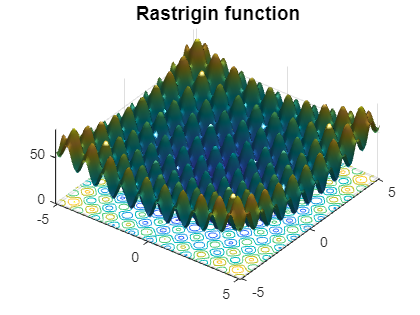

clc;
clear;

f6_bounds = [-5.12 5.12; -5.12 5.12];
f6 = @(x) rastriginsfcn(x);

plotobjective(f6, f6_bounds);
title('Rastrigin function','FontSize',14,'FontName','Helvetica');
hold off;

## **De Jong Function No.5**

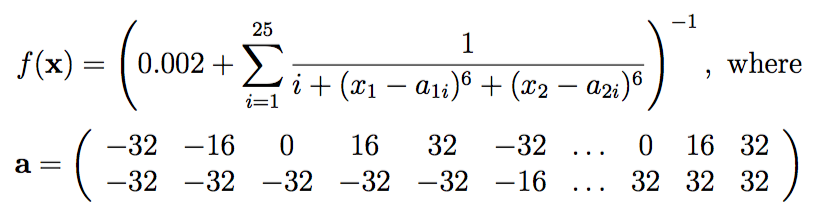


$$$$-65.536 \leq x_i \leq 65.536$$$$



$$$$\text{minimum at }f(-32, -32, \cdots, -32) = 0.998$$

$$


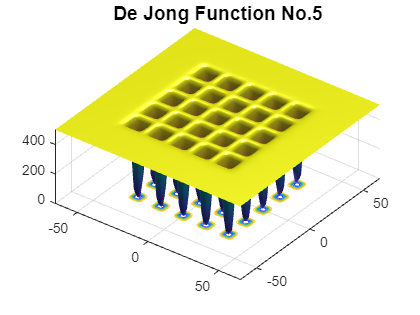

clc;
clear;

f5_bounds = [-65.536 65.536; -65.536 65.536];
f5 = @(x) dejong5fcn(x);

plotobjective(f5, f5_bounds);
title('De Jong Function No.5','FontSize',14,'FontName','Helvetica');
hold off;

## **Rosenbrock function**


$$$$f(x_1 \cdots x_n) = \sum_{i=1}^{n-1} (100(x_i^2 - x_{i+1})^2 + (1-x_i)^2)$$
$$



$$$$-2.048 \leq x_i \leq 2.048$$$$



$$$$\text{minimum at }f(1, 1, \cdots, 1) = 0$$

$$


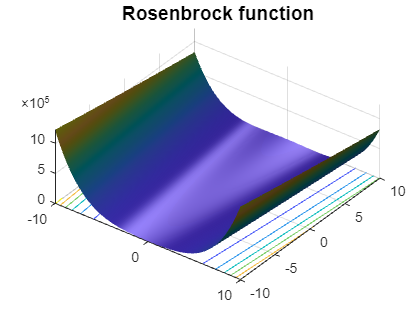

clc;
clear;

f2_bounds = [-10 10; -10 10];
f2 = @(x) rosenbrock(x);

plotobjective(f2, f2_bounds);
title('Rosenbrock function','FontSize',14,'FontName','Helvetica');
hold off;

## **Genetic Algorithm - GA**

% ----------------------------
%       Init settings        |
% ----------------------------
% number of dimensions
D = 2;
% number of restarts
RUNs = 1000;
% set up input function
func = f6;
func_bounds = f6_bounds;
% ----------------------------

% GA solver settings
% More specific on: https://www.mathworks.com/help/gads/ga.html?s_tid=doc_ta#mw_4a8bfdb9-7c4c-4302-8f47-d260b7a43e26
options = optimoptions( ...
    "ga", ...
    'PopulationSize',100, ...
    'SelectionFcn','selectionroulette', ...
    'MutationFcn','mutationpositivebasis', ...
    'CreationFcn','gacreationuniform', ...
    'FitnessLimit', 0.0001 ...
);

% compare variable
fval_comp = 100;

% init arrays and matrix for store parametres
time_o = zeros(length(RUNs));
fval_o = zeros(length(RUNs));
x_o = zeros(length(RUNs),length(RUNs));
g_o = zeros(length(RUNs));

for i=1:RUNs
    % start count time
    tic
    
    % GA solving
    [x,fval,exitflag,output,population,scores] = ga(func,D,options);
    
    % end count time
    time_o(i) = toc;
    
    % get best objective function value 
    if fval < fval_comp
        fval_comp = fval;
    end
    
    % save to initialized matrix finded global min
    for j=1:D
         x_o(j,i) = x(j);
    end
    
    % save to initialized arrays objective function value
    fval_o(i) = fval;

    % save to initialized arrays number of generations
    g_o(i) = output.generations;
end

Optimization terminated: minimum fitness limit reached.
Optimization terminated: minimum fitness limit reached.
Optimization terminated: minimum fitness limit reached.
Optimization terminated: minimum fitness limit reached.
Optimization terminated: minimum fitness limit reached.
Optimization terminated: minimum fitness limit reached.
Optimization terminated: minimum fitness limit reached.
Optimization terminated: minimum fitness limit reached.
Optimization terminated: minimum fitness limit reached.
Optimization terminated: minimum fitness limit reached.
Optimization terminated: minimum fitness limit reached.
Optimization terminated: minimum fitness limit reached.
Optimization terminated: minimum fitness limit reached.
Optimization terminated: minimum fitness limit reached.
Optimization terminated: minimum fitness limit reached.
Optimization terminated: minimum fitness limit reached.
Optimization terminated: minimum fitness limit reached.
Optimization terminated: minimum fitness limit r

i = find(fval_o == fval_comp);
fprintf('The most optimal point found:');

The most optimal point found:

for j=1:length(x)
    fprintf('x%d: %6f \n',j,x_o(j,i))
end

x1: -0.000019 
x2: 0.000005 


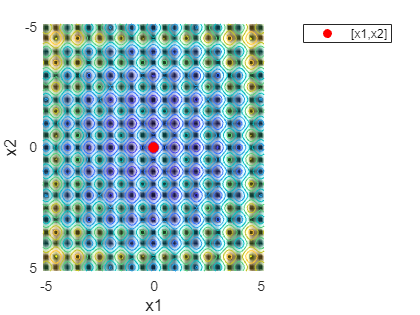

% Plot finded minimum if 2D
if D == 2
    plotobjective(func, func_bounds);
    view([0,-90]);
    hold on;
    
    point = scatter(x_o(1,i),x_o(2,i),50,'filled','o','MarkerEdgeColor','red','MarkerFaceColor','red');
    xlabel('x1','FontSize',12,'FontName','Helvetica');
    ylabel('x2','FontSize',12,'FontName','Helvetica');
    legend(point,'[x1,x2]');
    hold off;
end

## GA results statistics

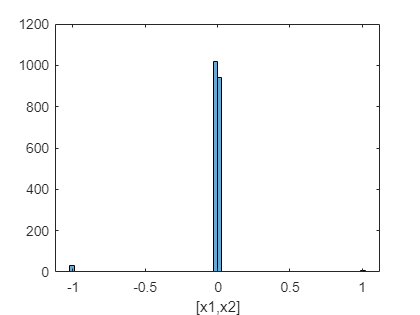

% histogram of finded global mins
histogram(x_o)
xlabel('[x1,x2]')

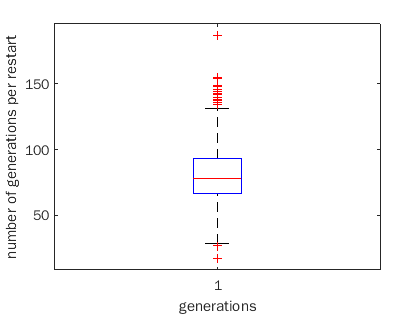


% boxplot of generations
boxplot(g_o)
xlabel('generations')
ylabel('number of generations per restart')

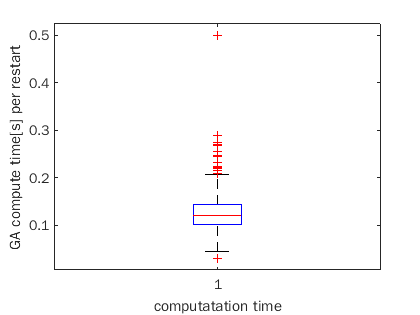


% boxplot of computing time
boxplot(time_o)
xlabel('computatation time')
ylabel('GA compute time[s] per restart')


% table of points
% median
med_x = median(x_o,D);
% modus
mod_x = mode(x_o,D);
% Standard deviation
std_x = std(x_o,1,D);
% maximum
max_x = max(x_o,[],D);
% minimum
min_x = min(x_o,[],D);
x = table((med_x),(mod_x),(std_x),(max_x),(min_x),'VariableNames',{'median','modus','std','max','min'})

x = 2×5 table
      median        modus        std        max        min   
    ___________    ________    _______    _______    ________

    -2.0689e-05      -0.995    0.15983    0.99499      -0.995
    -1.0929e-05    -0.99498    0.11746    0.99496    -0.99498



% table of  objective function
% median
med_f = median(fval_o);
% modus
mod_f = mode(fval_o);
% standard deviation
std_f = std(fval_o);
% maximum
max_f = max(fval_o);
% minimum
min_f = min(fval_o);
f = table((med_f),(mod_f),(std_f),(max_f),(min_f),'VariableNames',{'median','modus','std','max','min'})

f = 1×5 table
      median        modus         std        max         min    
    __________    __________    _______    _______    __________

    4.9201e-05    7.3378e-08    0.19506    0.99496    7.3378e-08



% computing time
% median
med_t = median(time_o);
% modus
mod_t = mode(time_o);
% standard deviation
std_t = std(time_o);
% maximum
max_t = max(time_o);
% minimum
min_t = min(time_o);
t = table((med_t),(mod_t),(std_t),(max_t),(min_t),'VariableNames',{'median','modus','std','max','min'})

t = 1×5 table
    median      modus        std        max        min   
    _______    ________    ________    ______    ________

    0.12076    0.082587    0.037558    0.5002    0.029925



% table of generations
% median
med_g = median(g_o);
% modus
mod_g = mode(g_o);
% standard deviation
std_g = std(g_o);
% maximum
max_g = max(g_o);
% minimum
min_g = min(g_o);
g = table((med_g),(mod_g),(std_g),(max_g),(min_g),'VariableNames',{'median','modus','std','max','min'})

g = 1×5 table
    median    modus     std      max    min
    ______    _____    ______    ___    ___

      78       74      21.458    187    17 


## Simulated Annealing - SA

% ----------------------------
%       Init settings        |
% ----------------------------
% number of dimensions
D = 2;
% number of restarts
RUNs = 1000;
% set up input function
func = f6;
func_bounds = f6_bounds;
% ----------------------------

% compare variable
fval_comp = 100;

% init arrays and matrix for store parametres
time_o = zeros(length(RUNs));
fval_o = zeros(length(RUNs));
x_o = zeros(length(RUNs),length(RUNs));
g_o = zeros(length(RUNs));

%  defined starting point: 50
x0 = ones(1,D)*50

x0 =     50    50



for i=1:RUNs
    % start count time
    tic
    
    % SA solver in default settings
    [x,fval,exitflag,output] = simulannealbnd(func,x0);
    
    % end count time
    time_o(i) = toc;
    
    % get best objective function value 
    if fval < fval_comp
        fval_comp = fval;
    end
    
    % save to initialized matrix finded global min
    for j=1:D
         x_o(j,i) = x(j);
    end
    
    % save to initialized arrays objective function value
    fval_o(i) = fval;
end

Optimization terminated: change in best function value less than options.FunctionTolerance.
Optimization terminated: change in best function value less than options.FunctionTolerance.
Optimization terminated: change in best function value less than options.FunctionTolerance.
Optimization terminated: change in best function value less than options.FunctionTolerance.
Optimization terminated: change in best function value less than options.FunctionTolerance.
Optimization terminated: change in best function value less than options.FunctionTolerance.
Optimization terminated: change in best function value less than options.FunctionTolerance.
Optimization terminated: change in best function value less than options.FunctionTolerance.
Optimization terminated: change in best function value less than options.FunctionTolerance.
Optimization terminated: change in best function value less than options.FunctionTolerance.
Optimization terminated: change in best function value less than options.Functio

i = find(fval_o == fval_comp);
fprintf('The most optimal point found:');

The most optimal point found:

for j=1:length(x)
    fprintf('x%d: %6f \n',j,x_o(j,i))
end

x1: -0.000000 
x2: 0.000000 


% Plot finded minimum if 2D
if D == 2
    plotobjective(func, func_bounds);
    view([0,-90]);
    hold on;
    
    point = scatter(x_o(1,i),x_o(2,i),50,'filled','o','MarkerEdgeColor','red','MarkerFaceColor','red');
    xlabel('x1','FontSize',12,'FontName','Helvetica');
    ylabel('x2','FontSize',12,'FontName','Helvetica');
    legend(point,'[x1,x2]');
    hold off;
end

## SA results statistics

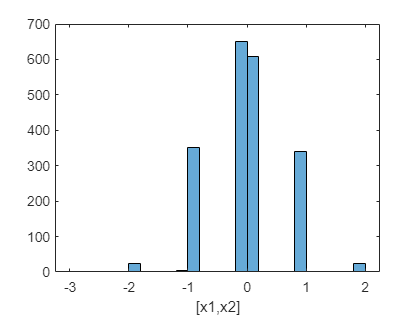

% histogram of finded global mins
histogram(x_o)
xlabel('[x1,x2]')

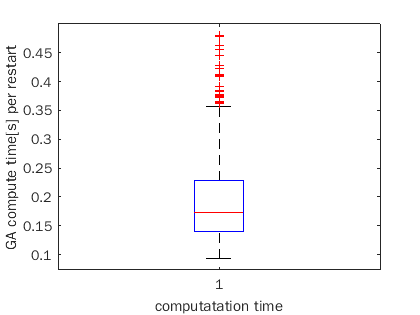


% boxplot of computing time
boxplot(time_o)
xlabel('computatation time')
ylabel('GA compute time[s] per restart')


% table of points
% median
med_x = median(x_o,D);
% modus
mod_x = mode(x_o,D);
% Standard deviation
std_x = std(x_o,1,D);
% maximum
max_x = max(x_o,[],D);
% minimum
min_x = min(x_o,[],D);
x = table((med_x),(mod_x),(std_x),(max_x),(min_x),'VariableNames',{'median','modus','std','max','min'})

x = 2×5 table
      median        modus       std       max        min  
    ___________    _______    _______    ______    _______

    -4.3587e-07    -2.9848    0.65915    1.9904    -2.9848
    -1.2828e-07    -1.9901    0.66596      1.99    -1.9901



% table of  objective function
% median
med_f = median(fval_o);
% modus
mod_f = mode(fval_o);
% standard deviation
std_f = std(fval_o);
% maximum
max_f = max(fval_o);
% minimum
min_f = min(fval_o);
f = table((med_f),(mod_f),(std_f),(max_f),(min_f),'VariableNames',{'median','modus','std','max','min'})

f = 1×5 table
    median       modus        std       max         min    
    _______    __________    ______    ______    __________

    0.99496    5.2296e-12    1.0387    8.9546    5.2296e-12



% computing time
% median
med_t = median(time_o);
% modus
mod_t = mode(time_o);
% standard deviation
std_t = std(time_o);
% maximum
max_t = max(time_o);
% minimum
min_t = min(time_o);
t = table((med_t),(mod_t),(std_t),(max_t),(min_t),'VariableNames',{'median','modus','std','max','min'})

t = 1×5 table
    median      modus       std       max        min   
    _______    _______    _______    ______    ________

    0.17343    0.10953    0.06819    0.4803    0.092744


function scores = rosenbrock(xin)
    % Rosenbrock function
    % implemented by https://en.wikipedia.org/wiki/Rosenbrock_function
    scores = zeros(size(xin,1),1);
    for i = 1:size(xin,1)
        p = xin(i,:);
        sum = 0;
        for j = 1:length(p)-1
            sum = sum +100*((p(j+1)-p(j)^2)^2+(p(j)-1)^2);
        end
        scores(i) = sum;
    end
end